Processing Frame 1


File: Frame_5.csv


Background Median = 49.00


Background SD     = 30.98


Threshold         = 18.02


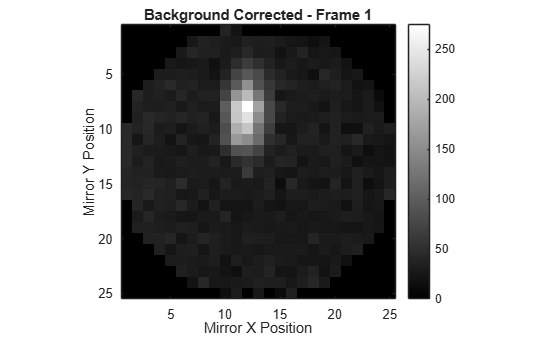


Maximum background-corrected count = 274.48


High-count threshold = 137.24


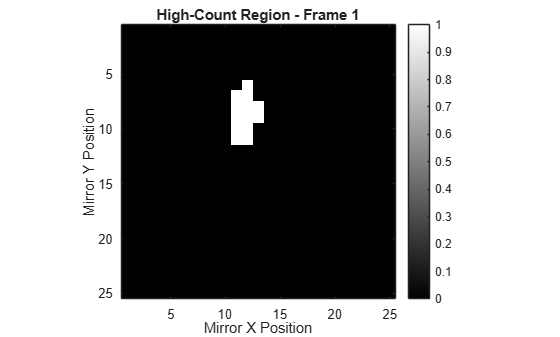

Star centre:


Pixel X = 17.329


Pixel Y = 11.754


Mirror X = 0.088895


Mirror Y = -0.025981


Processing Frame 2


File: Frame_4.csv


Background Median = 134.00


Background SD     = 42.66


Threshold         = 91.34


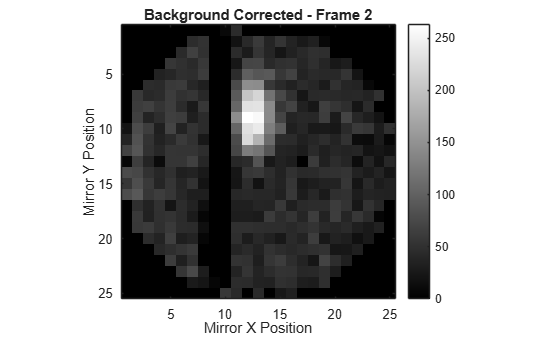


Maximum background-corrected count = 262.91


High-count threshold = 131.46


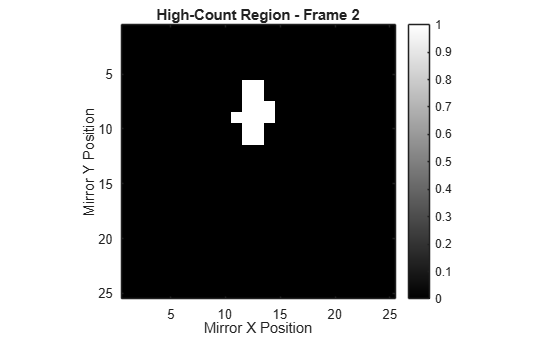

Star centre:


Pixel X = 17.344


Pixel Y = 12.567


Mirror X = 0.089211


Mirror Y = -0.009035


Processing Frame 3


File: Frame_3.csv


Background Median = 117.00


Background SD     = 46.13


Threshold         = 70.87


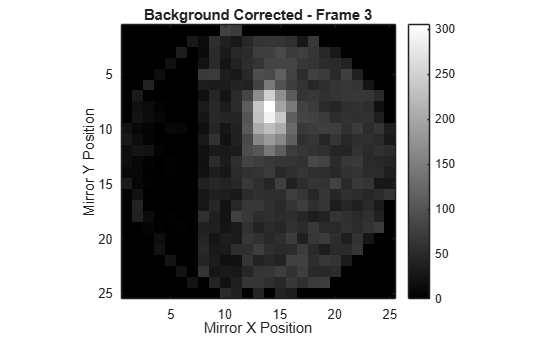


Maximum background-corrected count = 305.13


High-count threshold = 152.57


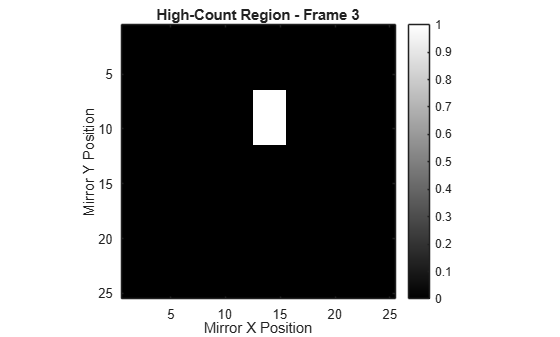

Star centre:


Pixel X = 17.079


Pixel Y = 13.992


Mirror X = 0.083715


Mirror Y = 0.020682


Processing Frame 4


File: Frame_2.csv


Background Median = 131.00


Background SD     = 37.68


Threshold         = 93.32


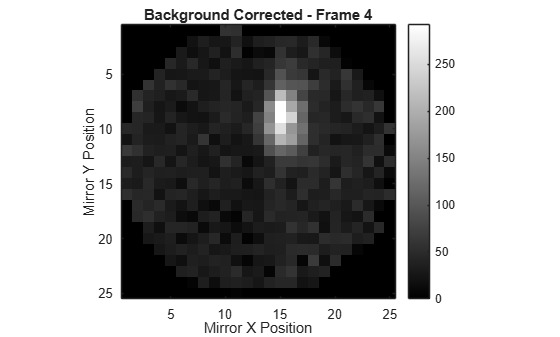


Maximum background-corrected count = 291.93


High-count threshold = 145.97


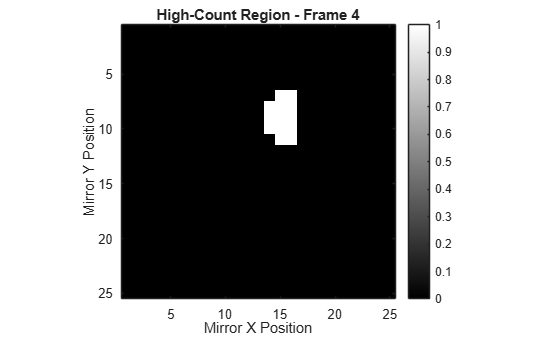

Star centre:


Pixel X = 17.001


Pixel Y = 15.172


Mirror X = 0.082091


Mirror Y = 0.045277


Processing Frame 5


File: Frame_1.csv


Background Median = 65.00


Background SD     = 32.69


Threshold         = 32.31


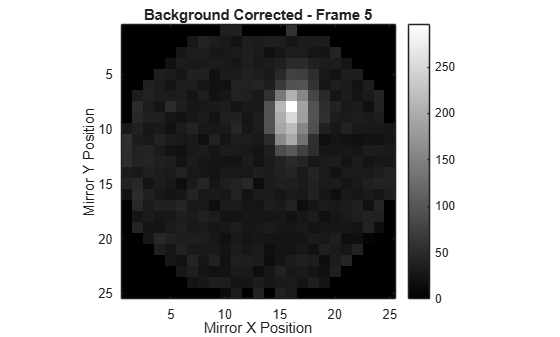


Maximum background-corrected count = 295.69


High-count threshold = 147.85


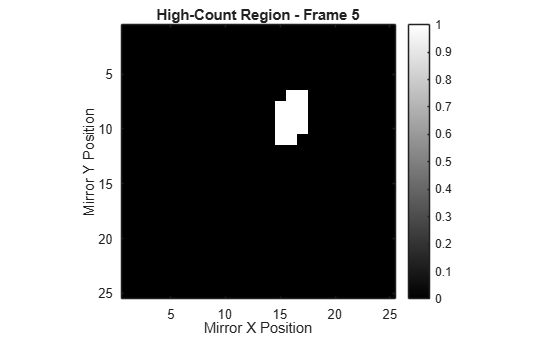

Star centre:


Pixel X = 17.055


Pixel Y = 15.970


Mirror X = 0.083213


Mirror Y = 0.061906


%% ============================================================
% MOVING OBJECT TRACKING FROM 5 CSV FRAMES
%
% Mirror Position
%       ->
% SPC Frame Reconstruction
%       ->
% Background Correction
%       ->
% High-Count Detection
%       ->
% Star Centre
%       ->
% Mirror X/Y Position
%       ->
% Trajectory
% ============================================================

clear; clc; close all

%% ============================================================
% SELECT 5 CSV FILES
% ============================================================

folder = '\\userfs\bh1308\w2k\Desktop\Single Photon Camera\CSV';

[filenames, pathname] = uigetfile( ...
    fullfile(folder,'*.csv'), ...
    'Select 5 Photon Scan Files', ...
    'MultiSelect','on');

if isequal(filenames,0)
    error('No files selected.');
end

if ischar(filenames)
    filenames = {filenames};
end

Nframes = length(filenames);

if Nframes ~= 5
    error('Please select exactly 5 CSV files.');
end


%% ============================================================
% SCAN PARAMETERS
% ============================================================

Nx = 25;
Ny = 25;


%% ============================================================
% HIGH-COUNT REGION PARAMETERS
% ============================================================

thresholdFraction = 0.5;


%% ============================================================
% STORAGE
% ============================================================

Photon_images = cell(Nframes,1);
Bright_regions = cell(Nframes,1);

trackedX = zeros(Nframes,1);
trackedY = zeros(Nframes,1);

pixelX = zeros(Nframes,1);
pixelY = zeros(Nframes,1);

thresholds = zeros(Nframes,1);
brightThresholds = zeros(Nframes,1);


%% ============================================================
% PROCESS EACH FRAME
% ============================================================

for frameNumber = 1:Nframes

    fprintf('\n')
    fprintf('========================================\n')
    fprintf('Processing Frame %d\n',frameNumber)
    fprintf('File: %s\n',filenames{frameNumber})
    fprintf('========================================\n')


    %% ========================================================
    % LOAD CSV
    % ========================================================

    data = readtable(fullfile(pathname,filenames{frameNumber}));

    mirrorX = data.X;
    mirrorY = data.Y;
    Counts  = data.Count;


    %% ========================================================
    % CONVERT MIRROR POSITIONS TO PIXEL POSITIONS
    % ========================================================

    x_grid = linspace(min(mirrorX), max(mirrorX), Nx);
    y_grid = linspace(min(mirrorY), max(mirrorY), Ny);

    SPC_counts = zeros(Ny,Nx);
    SPC_visits = zeros(Ny,Nx);


    for k = 1:length(Counts)

        [~,x_index] = min(abs(x_grid - mirrorX(k)));
        [~,y_index] = min(abs(y_grid - mirrorY(k)));

        SPC_counts(y_index,x_index) = ...
            SPC_counts(y_index,x_index) + Counts(k);

        SPC_visits(y_index,x_index) = ...
            SPC_visits(y_index,x_index) + 1;

    end


    %% ========================================================
    % CALCULATE AVERAGE WHERE MEASUREMENTS EXIST
    % ========================================================

    SPC_frame = zeros(Ny,Nx);

    valid = SPC_visits > 0;

    SPC_frame(valid) = ...
        SPC_counts(valid) ./ SPC_visits(valid);


    %% ========================================================
    % CALCULATE BACKGROUND THRESHOLD
    % ========================================================

    backgroundCounts = Counts;

    backgroundmedian = median(backgroundCounts);
    sigma = std(backgroundCounts);

    k_threshold = -1;

    threshold = backgroundmedian + ...
                k_threshold*sigma;

    thresholds(frameNumber) = threshold;

    fprintf('Background Median = %.2f\n',backgroundmedian);
    fprintf('Background SD     = %.2f\n',sigma);
    fprintf('Threshold         = %.2f\n',threshold);


    %% ========================================================
    % BACKGROUND CORRECTION
    % ========================================================

    Photon_image = max(SPC_frame - threshold,0);

    Photon_images{frameNumber} = Photon_image;


    %% ========================================================
    % DISPLAY BACKGROUND CORRECTED IMAGE
    % ========================================================

    figure

    imagesc(rot90(Photon_image))

    axis image
    axis ij
    colormap(gray)
    colorbar

    title(sprintf('Background Corrected - Frame %d', ...
        frameNumber))

    xlabel('Mirror X Position')
    ylabel('Mirror Y Position')


    %% ========================================================
    % FIND MAXIMUM COUNT
    % ========================================================

    maxCount = max(Photon_image(:));

    fprintf('\nMaximum background-corrected count = %.2f\n', ...
        maxCount);


    %% ========================================================
    % HIGH-COUNT THRESHOLD
    % ========================================================

    brightThreshold = ...
        thresholdFraction * maxCount;

    brightThresholds(frameNumber) = ...
        brightThreshold;

    fprintf('High-count threshold = %.2f\n', ...
        brightThreshold);


    %% ========================================================
    % CREATE HIGH-COUNT REGION
    % ========================================================

    brightRegion = Photon_image >= brightThreshold;

    Bright_regions{frameNumber} = brightRegion;


    %% ========================================================
    % DISPLAY HIGH-COUNT REGION
    % ========================================================

    figure

    imagesc(rot90(brightRegion))

    axis image
    axis ij
    colormap(gray)
    colorbar

    title(sprintf('High-Count Region - Frame %d', ...
        frameNumber))

    xlabel('Mirror X Position')
    ylabel('Mirror Y Position')


    %% ========================================================
    % CALCULATE CENTRE OF HIGH-COUNT REGION
    % ========================================================

    [Xgrid,Ygrid] = meshgrid(1:Nx,1:Ny);

    Xbright = Xgrid(brightRegion);
    Ybright = Ygrid(brightRegion);

    Ibright = Photon_image(brightRegion);


    %% ========================================================
    % CHECK THAT SIGNAL EXISTS
    % ========================================================

    if isempty(Ibright) || sum(Ibright) == 0

        warning('No high-count region found in Frame %d', ...
            frameNumber);

        trackedX(frameNumber) = NaN;
        trackedY(frameNumber) = NaN;

        continue

    end


    %% ========================================================
    % INTENSITY-WEIGHTED CENTRE
    % ========================================================

    starCentreX = ...
        sum(Xbright .* Ibright) / sum(Ibright);

    starCentreY = ...
        sum(Ybright .* Ibright) / sum(Ibright);


    %% ========================================================
    % STORE PIXEL CENTRE
    % ========================================================

    pixelX(frameNumber) = starCentreX;
    pixelY(frameNumber) = starCentreY;


    %% ========================================================
    % MAP CENTRE TO MIRROR COORDINATES
    % ========================================================

    mirrorCentreX = interp1( ...
        1:Nx, ...
        x_grid, ...
        starCentreX, ...
        'linear');

    mirrorCentreY = interp1( ...
        1:Ny, ...
        y_grid, ...
        starCentreY, ...
        'linear');


    %% ========================================================
    % STORE TRACKED POSITION
    % ========================================================

    trackedX(frameNumber) = mirrorCentreX;
    trackedY(frameNumber) = mirrorCentreY;


    %% ========================================================
    % PRINT CENTRE
    % ========================================================

    fprintf('\n')
    fprintf('Star centre:\n')

    fprintf('Pixel X = %.3f\n',starCentreX);
    fprintf('Pixel Y = %.3f\n',starCentreY);

    fprintf('Mirror X = %.6f\n',mirrorCentreX);
    fprintf('Mirror Y = %.6f\n',mirrorCentreY);

end

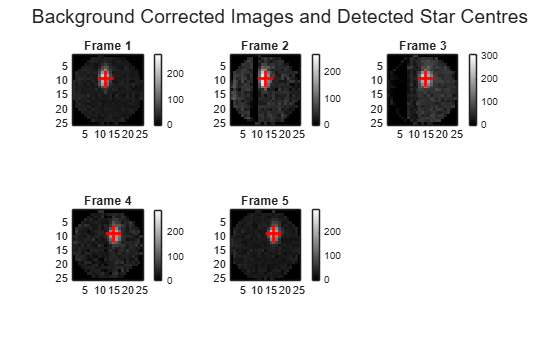



%% ============================================================
% FINAL FIGURE:
% ALL 5 BACKGROUND-CORRECTED FRAMES + DETECTED CENTRES
% ============================================================

figure

for n = 1:Nframes

    subplot(2,3,n)

    imagesc(rot90(Photon_images{n}))

    axis image
    axis ij
    colormap(gray)
    colorbar

    hold on

    % Convert tracked mirror position back to pixel position
    [~,x_pixel] = min(abs(x_grid - trackedX(n)));
    [~,y_pixel] = min(abs(y_grid - trackedY(n)));

    % Correct coordinate conversion for rot90()
    displayX = y_pixel;
    displayY = Nx - x_pixel + 1;

    % Plot detected centre
    plot(displayX,displayY, ...
        'r+', ...
        'MarkerSize',12, ...
        'LineWidth',2)

    title(sprintf('Frame %d',n))

    hold off

end

sgtitle('Background Corrected Images and Detected Star Centres')



%% ============================================================
% CALCULATED STAR TRAJECTORY
% ============================================================

figure

plot(trackedX,trackedY, ...
    'r-o', ...
    'LineWidth',2, ...
    'MarkerSize',8)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [0.0889 0.0892 0.0837 0.0821 0.0832]
              YData: [-0.0260 -0.0090 0.0207 0.0453 0.0619]

  Show all properties


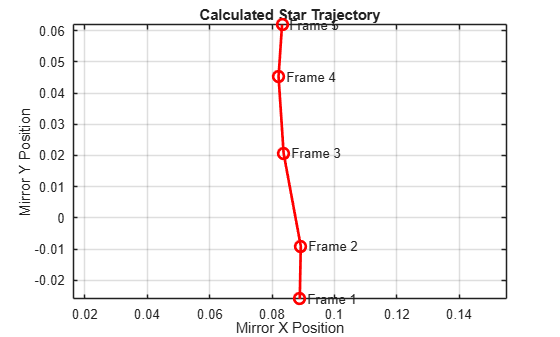


grid on
axis equal

xlabel('Mirror X Position')
ylabel('Mirror Y Position')

title('Calculated Star Trajectory')

hold on


%% ============================================================
% LABEL EACH FRAME
% ============================================================

for n = 1:Nframes

    text(trackedX(n), ...
         trackedY(n), ...
         sprintf('  Frame %d',n), ...
         'FontSize',10)

end

hold off



%% ============================================================
% PRINT TRAJECTORY
% ============================================================

fprintf('\n')
fprintf('===============================================\n')

fprintf('             STAR TRAJECTORY\n')

             STAR TRAJECTORY


fprintf('===============================================\n')


fprintf('Frame        X Position        Y Position\n')

Frame        X Position        Y Position


fprintf('-----------------------------------------------\n')

-----------------------------------------------



for n = 1:Nframes

    fprintf('%3d        %12.6f       %12.6f\n', ...
        n, ...
        trackedX(n), ...
        trackedY(n));

end

  1            0.088895          -0.025981
  2            0.089211          -0.009035
  3            0.083715           0.020682
  4            0.082091           0.045277
  5            0.083213           0.061906




%% ============================================================
% FRAME-TO-FRAME MOTION
% ============================================================

dx = diff(trackedX);
dy = diff(trackedY);

fprintf('\n')
fprintf('Frame-to-frame motion:\n')

Frame-to-frame motion:


fprintf('-----------------------------------------------\n')

-----------------------------------------------



for n = 1:Nframes-1

    fprintf('Frame %d -> %d :  dx = %10.6f   dy = %10.6f\n', ...
        n, ...
        n+1, ...
        dx(n), ...
        dy(n));

end

Frame 1 -> 2 :  dx =   0.000316   dy =   0.016946
Frame 2 -> 3 :  dx =  -0.005496   dy =   0.029717
Frame 3 -> 4 :  dx =  -0.001624   dy =   0.024595
Frame 4 -> 5 :  dx =   0.001122   dy =   0.016629




%% ============================================================
% AVERAGE VELOCITY
% ============================================================

vx = mean(dx,'omitnan');
vy = mean(dy,'omitnan');

fprintf('\n')
fprintf('Average velocity:\n')

Average velocity:



fprintf('vx = %.6f mirror units/frame\n',vx)

vx = -0.001421 mirror units/frame


fprintf('vy = %.6f mirror units/frame\n',vy)

vy = 0.021972 mirror units/frame




%% ============================================================
% TOTAL DISPLACEMENT
% ============================================================

totalDx = trackedX(end) - trackedX(1);
totalDy = trackedY(end) - trackedY(1);

fprintf('\n')
fprintf('Total displacement:\n')

Total displacement:



fprintf('dx = %.6f\n',totalDx)

dx = -0.005682


fprintf('dy = %.6f\n',totalDy)

dy = 0.087887




%% ============================================================
% TOTAL TRAJECTORY DISTANCE
% ============================================================

stepDistance = sqrt(dx.^2 + dy.^2);

totalDistance = sum(stepDistance,'omitnan');

fprintf('\n')
fprintf('Total trajectory distance = %.6f mirror units\n', ...
    totalDistance)

Total trajectory distance = 0.088485 mirror units
